# Plot urban landscapes

## plot the host landscapes and save to file

clear vars
close all

### EDIT TO YOUR LOCAL PATH

TopPath = 'D:/Cerian/OneDrive - University of Cambridge/UrbanTreeModel/ModelCodeForPublic2023/UrbanEpidemicModel2023';

addpath(TopPath);
addpath([TopPath,'/dataPrepare']);
addpath([TopPath,'/dataPrepare/plot_dataPrepare_functions']);
addpath([TopPath,'/dataPrepare/SyntheticLandscapes']);

**Only need to use mkdir command once (uncomment - or create in windows explorer)**

%mkdir([StartMyPath,'dataPrepare/LandscapeFigures']);
PathToFigs  = ([TopPath,'/dataPrepare/LandscapeFigures']); 


### Colormaps

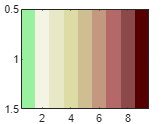

ColAll = [136 204 238]./255;
ColRoad = [170 68 153]./255;
ColPark = [17 119 51]./255;
ColRoadMap = [200 201 204]./255;
ColInfectRoadMap = colormap(flipud(pink(9)));
LightGreen = [0.6 0.9412 0.6235];
ColInfectRoadMap(1,:) = LightGreen;
imagesc(0:8)
colormap(ColInfectRoadMap)

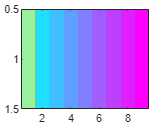


BackgrdColMap = [ 0 0 0; ColRoadMap];
imagesc(0:8)
ColInfectMap = cool(9);
ColInfectMap(1,:) = LightGreen;
colormap(ColInfectMap)

## Host landscape name

LandscapeType = 'Matern'; % Matern or Random or All
NumLandscapes = 4;
for LandscapeID = 1:NumLandscapes
urbanLandscapeName = ['synth_',LandscapeType,'_',num2str(LandscapeID),'_UrbanLandscape'];
ShortLandscapeName = [LandscapeType,'_',num2str(LandscapeID)];

### Load landscape data and convert grid locations to matrix

sim_out = load([urbanLandscapeName '.mat']);
[XGridLoc,YGridLoc,NumParkTrees] = xyz2grid(sim_out.urbanLandscape.gridcenters(:,1),sim_out.urbanLandscape.gridcenters(:,2),sim_out.urbanLandscape.parkpopulation);
XGridLocList = XGridLoc(:); 
YGridLocList = YGridLoc(:); 
XRoadLocList = sim_out.urbanLandscape.roadcenters(:,1); 
YRoadLocList = sim_out.urbanLandscape.roadcenters(:,2); 

reformat data

NumParkTreesList = NumParkTrees(:);
NumRoadTreesList = sim_out.urbanLandscape.roadpopulation;
maxTreesinParkCell = max(NumParkTreesList);
maxTreesinRoadCell = max(NumRoadTreesList);
LocWithParkTree = find(NumParkTreesList>0);
LocWithRoadTree = find(NumRoadTreesList>0);

## Plot of host landscape

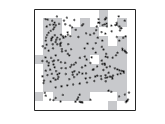

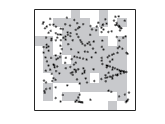

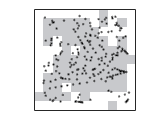

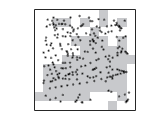

RoadOn = 1;
ParkOn = 1;
FxPlotRasterOfHostLandscape(XGridLoc,YGridLoc,NumParkTrees,XRoadLocList,YRoadLocList, LocWithRoadTree, BackgrdColMap,ColInfectMap,ColInfectRoadMap,ShortLandscapeName,RoadOn,ParkOn,PathToFigs);
end

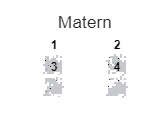

% combine plots into one figure: grey squares are grid squares containing
% at least one park tree of Species X, black points are road trees of
% Species X
PlotLandscape = 1;
if PlotLandscape > 0 
 
 figure
 tiledlayout(2,2,"TileSpacing","none")
 for i = 1:4
     
     tilenum = i;
     fignum = tilenum;
     nexttile(tilenum)
     A = imread([PathToFigs,'/',LandscapeType,'_',num2str(fignum),'All.png']);
     imshow(A,'border','tight')
     title(num2str(fignum))
     
 end
 sgtitle(LandscapeType)
end